parameters
%%%Elimination of magnetic Field
%%% PID Simulation
 salidas=sim('inLoopSimu_pid.slx','SrcWorkspace','current');

Found algebraic loop containing: 
inLoopSimu_pid/ISNMTB TestBed/myPID/Discrete Derivative/TSamp
inLoopSimu_pid/ISNMTB TestBed/myPID/Discrete Derivative/Diff (algebraic variable)
inLoopSimu_pid/ISNMTB TestBed/myPID/MATLAB Function
inLoopSimu_pid/ISNMTB TestBed/Saturation (discontinuity)
inLoopSimu_pid/ISNMTB TestBed/ISNMTB/Interpreted MATLAB Function


 yout       = salidas.get('yout');
 myPid.t    = yout{1}.Values.Time;
 temp.e    = yout{1}.Values.Data;
 temp.u    = yout{2}.Values.Data;
 temp.sp   = yout{3}.Values.Data;
 temp.i    = yout{4}.Values.Data;
 temp.b    = yout{5}.Values.Data;
 temp.p    = yout{6}.Values.Data;
 temp.r    = yout{7}.Values.Data;

 myPid.e    = zeros(size(temp.e, 3),3);
 myPid.u    = zeros(size(temp.u, 3),3);
 myPid.sp   = temp.sp;
 myPid.i    = temp.i;
 myPid.b    = zeros(size(temp.b, 3),3);
 myPid.p    = zeros(size(temp.p, 3),3);
 myPid.r    = temp.r;

 % Display each slice of the 3D array
 numSlices = size(temp.e, 3);
    for j = 1:numSlices
        %fprintf('val(:,:, %d) =\n\n', j);
        myPid.e(j,:) = temp.e(:, :, j);
        myPid.u(j,:) = temp.u(:, :, j);
        myPid.b(j,:) = temp.b(:, :, j);
        myPid.p(j,:) = temp.p(:, :, j);
    end
 %Define error, control signal and output


clear salidas temp yout

 %%%Elimination of magnetic Field
%%% PID Simulation
 salidas=sim('inLoopSimu_adapt.slx','SrcWorkspace','current');

Found algebraic loop containing: 
inLoopSimu_adapt/ISNMTB TestBed/Controller/Interpreted MATLAB Function
inLoopSimu_adapt/ISNMTB TestBed/Saturation (discontinuity)
inLoopSimu_adapt/ISNMTB TestBed/ISNMTB/Interpreted MATLAB Function
inLoopSimu_adapt/ISNMTB TestBed/Gain
inLoopSimu_adapt/ISNMTB TestBed/Sum (algebraic variable)


 yout       = salidas.get('yout');
 adaptive.t    = yout{1}.Values.Time;
 temp.e    = yout{1}.Values.Data;
 temp.u    = yout{2}.Values.Data;
 temp.sp   = yout{3}.Values.Data;
 temp.i    = yout{4}.Values.Data;
 temp.b    = yout{5}.Values.Data;
 temp.p    = yout{6}.Values.Data;
 temp.a    = yout{7}.Values.Data;
 temp.r    = yout{8}.Values.Data;

 adaptive.e    = zeros(size(temp.e, 3),3);
 adaptive.u    = temp.u;
 adaptive.sp   = temp.sp;
 adaptive.i    = temp.i;
 adaptive.b    = zeros(size(temp.b, 3),3);
 adaptive.p    = zeros(size(temp.p, 3),3);
 adaptive.a    = temp.a;
 adaptive.r    = temp.r;

 % Display each slice of the 3D array
 numSlices = size(temp.e, 3);
    for j = 1:numSlices
        %fprintf('val(:,:, %d) =\n\n', j);
        adaptive.e(j,:) = temp.e(:, :, j);
        adaptive.b(j,:) = temp.b(:, :, j);
        adaptive.p(j,:) = temp.p(:, :, j);
    end
 %Define error, control signal and output

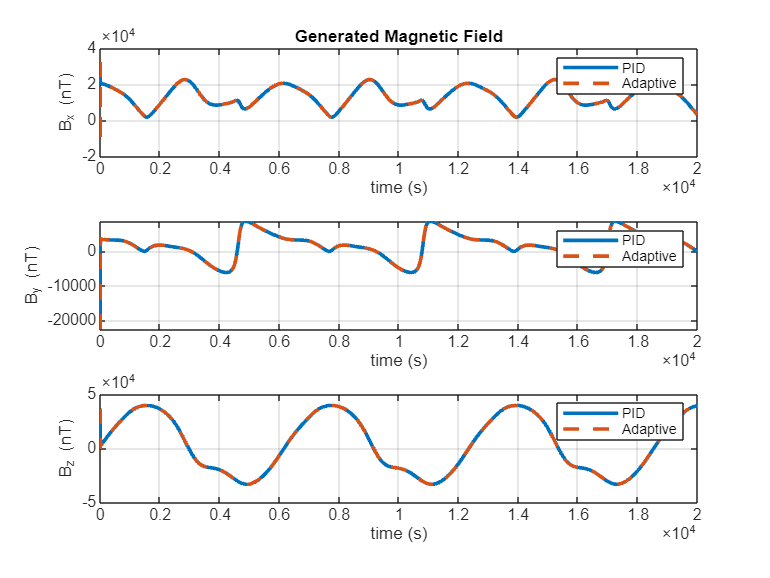

figure()
sp1 = subplot(3,1,1);
    p1 = plot(myPid.t,myPid.b(:,1),'LineWidth',2); hold on;
    %p1_r = plot(myPid.t,myPid.r(:,1),'LineWidth',1);
    p2 = plot(adaptive.t,adaptive.b(:,1),'LineWidth',2,'LineStyle','--','Marker','none'); grid on;
    %p2_r = plot(adaptive.t,adaptive.r(:,1),'LineWidth',1);
    %p2_r = plot(adaptive.t,adaptive.sp(:,1),'LineWidth',1);
    title('Generated Magnetic Field');
    xlabel('time (s)'); ylabel('B_x (nT)');
    legend([p1,p2],'PID','Adaptive')
sp2 = subplot(3,1,2);
    p1=plot(myPid.t,myPid.b(:,2),'LineWidth',2); hold on;
    p2=plot(adaptive.t,adaptive.b(:,2),'LineWidth',2,'LineStyle','--','Marker','none'); grid on;
    xlabel('time (s)'); ylabel('B_y (nT)');
    legend([p1,p2],'PID','Adaptive');
sp3 = subplot(3,1,3);
    p1=plot(myPid.t,myPid.b(:,3),'LineWidth',2); hold on;
    p2=plot(adaptive.t,adaptive.b(:,3),'LineWidth',2,'LineStyle','--','Marker','none'); grid on;
    xlabel('time (s)'); ylabel('B_z (nT)');
    legend([p1,p2],'PID','Adaptive');
    linkaxes([sp1,sp2,sp3],'x');

    
% subplot(3,1,1)
% ylim([-0.026 0.027])
% subplot(3,1,2)
% ylim([-0.34 0.34])
% subplot(3,1,3)
% ylim([-1.15 1.15])

itse_pid      = trapz(myPid.t,myPid.e.^2);
itse_adaptive = trapz(adaptive.t,adaptive.e.^2);

disp('PID: ');disp(itse_pid);disp('Adaptive: ');disp(itse_adaptive)

PID: 
   1.0e+09 *

    0.0044    0.0594    2.5853

Adaptive: 
   1.0e+04 *

    5.9241    6.9681    6.9866



uwork_pid = trapz(myPid.t,myPid.u.^2);
uwork_adaptive = trapz(adaptive.t,adaptive.u.^2);
disp('PID: ');disp(uwork_pid);disp('Adaptive: ');disp(uwork_adaptive);

PID: 
   1.0e+06 *

    0.4871    0.1991    3.3065

Adaptive: 
   1.0e+06 *

    0.4872    0.2016    3.3144



ts_pid_x = calculateSettlementTime(myPid.e(:,1), myPid.t, 5/100*3.249E04)

ts_pid_x = 0.4809

ts_pid_y = calculateSettlementTime(myPid.e(:,2), myPid.t, 5/100*2.265E04)

ts_pid_y = 11.5529

ts_pid_z = calculateSettlementTime(myPid.e(:,3), myPid.t, 5/100*3.655E04)

ts_pid_z = 10.0161

ts_adaptive_x = calculateSettlementTime(adaptive.e(:,1), adaptive.t, 5/100*3.249E04)

ts_adaptive_x = 5.1792e-04

ts_adaptive_y = calculateSettlementTime(adaptive.e(:,2), adaptive.t, 5/100*2.265E04)

ts_adaptive_y = 1.7714e-04

ts_adaptive_z = calculateSettlementTime(adaptive.e(:,3), adaptive.t, 5/100*3.655E04)

ts_adaptive_z = 4.9128e-05

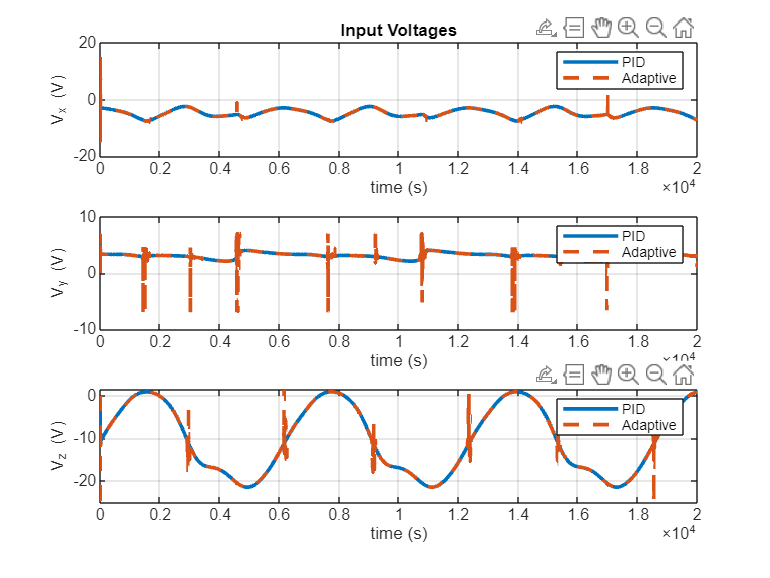


figure()
sp1=subplot(3,1,1);
    p1=plot(myPid.t,myPid.u(:,1),'LineWidth',2); hold on;
    p2=plot(adaptive.t,adaptive.u(:,1),'LineWidth',2,'LineStyle','--','Marker','none'); grid on;
    title('Input Voltages');
    xlabel('time (s)'); ylabel('V_x (V)');
    legend([p1,p2],'PID','Adaptive');
sp2=subplot(3,1,2);
    p1=plot(myPid.t,myPid.u(:,2),'LineWidth',2); hold on;
    p2=plot(adaptive.t,adaptive.u(:,2),'LineWidth',2,'LineStyle','--','Marker','none'); grid on;
    xlabel('time (s)'); ylabel('V_y (V)');
    legend([p1,p2],'PID','Adaptive');
sp3=subplot(3,1,3);
    p1=plot(myPid.t,myPid.u(:,3),'LineWidth',2); hold on;
    p2=plot(adaptive.t,adaptive.u(:,3),'LineWidth',2,'LineStyle','--','Marker','none'); grid on;
    xlabel('time (s)'); ylabel('V_z (V)');
    legend([p1,p2],'PID','Adaptive')
    linkaxes([sp1,sp2,sp3],'x');


% subplot(3,1,3)
%     xlim([183 1850]);
%     ylim([-11.2256 -11.2045]);
% subplot(3,1,1)
%     xlim([144 1811]);
%     ylim([-7.9668 -7.9625]);
% subplot(3,1,2)
%     xlim([144 1811]);
%     ylim([2.9101 2.9182]);

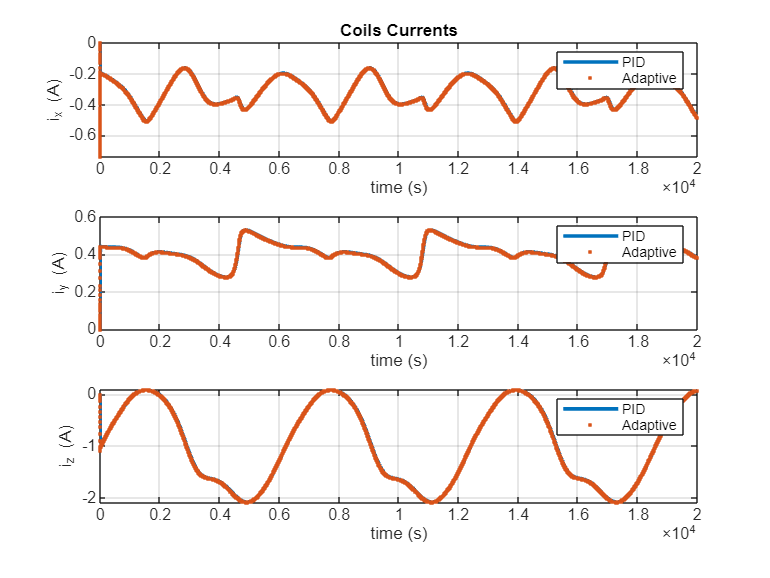

figure()
sp1 = subplot(3,1,1);
    p1=plot(myPid.t,myPid.i(:,1),'LineWidth',2); hold on;
    p2=plot(adaptive.t,adaptive.i(:,1),'LineWidth',2,'LineStyle','none','Marker','.'); grid on;
    xlabel('time (s)'); ylabel('i_x (A)');
    legend([p1,p2],'PID','Adaptive');
    title('Coils Currents');
sp2 = subplot(3,1,2);
    p1=plot(myPid.t,myPid.i(:,2),'LineWidth',2); hold on;
    p2=plot(adaptive.t,adaptive.i(:,2),'LineWidth',2,'LineStyle','none','Marker','.'); grid on;
    xlabel('time (s)'); ylabel('i_y (A)');
    legend([p1,p2],'PID','Adaptive');
sp3 = subplot(3,1,3);
    p1=plot(myPid.t,myPid.i(:,3),'LineWidth',2); hold on;
    p2=plot(adaptive.t,adaptive.i(:,3),'LineWidth',2,'LineStyle','none','Marker','.'); grid on;
    xlabel('time (s)'); ylabel('i_z (A)');
    legend([p1,p2],'PID','Adaptive');
    linkaxes([sp1,sp2,sp3],'x');

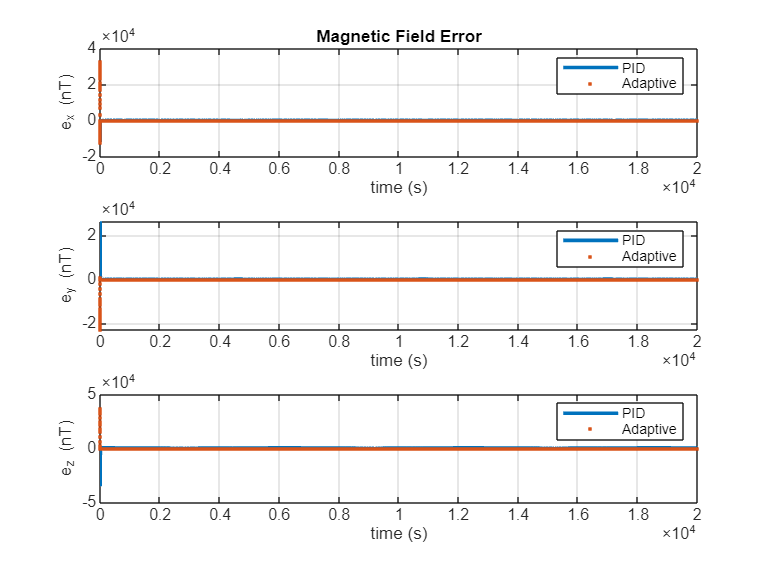

figure()
sp1 = subplot(3,1,1);
    p1=plot(myPid.t,myPid.e(:,1),'LineWidth',2); hold on;
    p2=plot(adaptive.t,adaptive.e(:,1),'LineWidth',2,'LineStyle','none','Marker','.'); grid on;
    xlabel('time (s)'); ylabel('e_x (nT)');
    legend([p1,p2],'PID','Adaptive');
    title('Magnetic Field Error');
sp2 = subplot(3,1,2);
    p1=plot(myPid.t,myPid.e(:,2),'LineWidth',2); hold on;
    p2=plot(adaptive.t,adaptive.e(:,2),'LineWidth',2,'LineStyle','none','Marker','.'); grid on;
    xlabel('time (s)'); ylabel('e_y (nT)');
    legend([p1,p2],'PID','Adaptive');
sp3 = subplot(3,1,3);
    p1=plot(myPid.t,myPid.e(:,3),'LineWidth',2); hold on;
    p2=plot(adaptive.t,adaptive.e(:,3),'LineWidth',2,'LineStyle','none','Marker','.'); grid on;
    xlabel('time (s)'); ylabel('e_z (nT)');
    legend([p1,p2],'PID','Adaptive');
    linkaxes([sp1,sp2,sp3],'x');

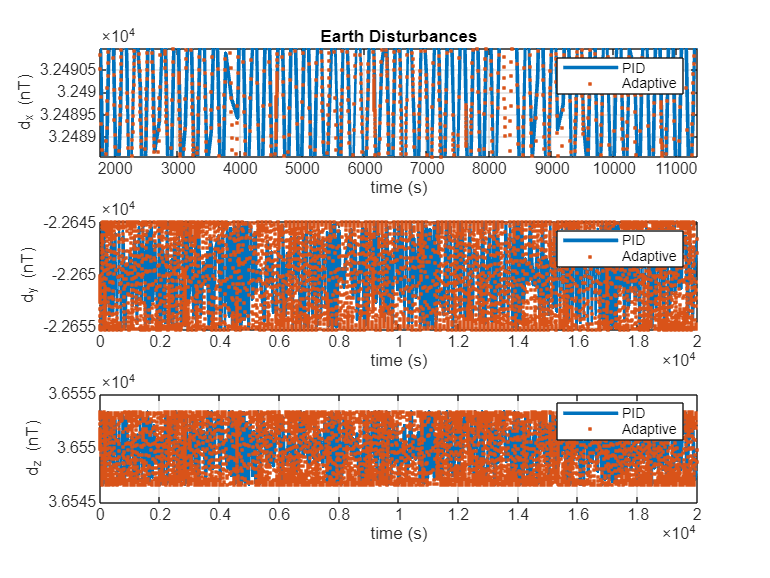

figure()
sp1 = subplot(3,1,1);
    p1=plot(myPid.t,myPid.p(:,1)*1E9,'LineWidth',2); hold on;
    p2=plot(adaptive.t,adaptive.p(:,1),'LineWidth',2,'LineStyle','none','Marker','.'); grid on;
    xlabel('time (s)'); ylabel('d_x (nT)');
    legend([p1,p2],'PID','Adaptive');
    title('Earth Disturbances');
SP2 = subplot(3,1,2);
    p1=plot(myPid.t,myPid.p(:,2)*1E9,'LineWidth',2); hold on;
    p2=plot(adaptive.t,adaptive.p(:,2),'LineWidth',2,'LineStyle','none','Marker','.'); grid on;
    xlabel('time (s)'); ylabel('d_y (nT)');
    legend([p1,p2],'PID','Adaptive');
SP3 = subplot(3,1,3);
    p1=plot(myPid.t,myPid.p(:,3)*1E9,'LineWidth',2); hold on;
    p2=plot(adaptive.t,adaptive.p(:,3),'LineWidth',2,'LineStyle','none','Marker','.'); grid on;
    xlabel('time (s)'); ylabel('d_z (nT)');
    legend([p1,p2],'PID','Adaptive');